# Matlab PMCSN

## Modello

Con questo live script da formalizzare a dovere viene provata la corrispondenza tra i valori analitici e quelli empirici trovati tramite la simulazione.

Il test viene effettuato con i seguenti parametri:


$$\begin{array}{l}
N_{\mathrm{server}} =3\\
\lambda_1 =6\\
\lambda_2 =6\ldotp 25\\
\mu {\;}_{1_{\mathrm{cloudlet}} } =0\ldotp 45\\
\mu {\;}_{2_{\mathrm{cloudlet}} } =0\ldotp 27\\
\mu {\;}_{1_{\mathrm{cloud}} } =0\ldotp 25\\
\mu {\;}_{2_{\mathrm{cloud}} } =0\ldotp 22
\end{array}$$


Siano arrivi e servizi di tasso esponenziale.

Il sistema è modellato nel seguente modo 

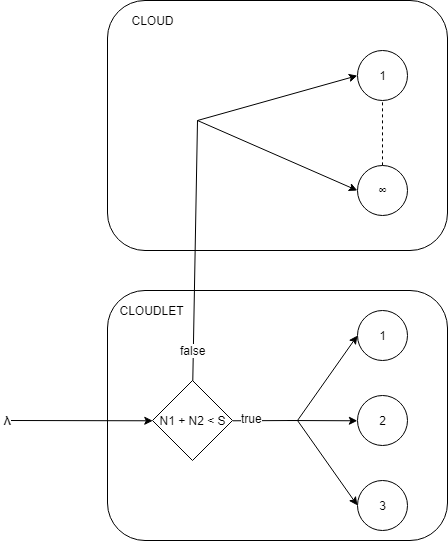

in particolare, da uno studio sulla catena di Markov relativa al solo sisema cloudlet si ha il seguente schema *scrivere anche il sistema di equazioni*

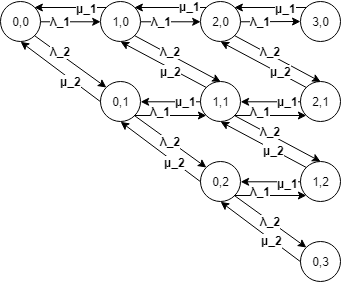

lambdaClassOne = 6;
lambdaClassTwo = 6.25;
cloudletMuClassOne = 0.45;
cloudletMuClassTwo = 0.27;
cloudMuClassOne = 0.25;
cloudMuClassTwo = 0.22;

Per prima cosa risolviamo la catena di markov relativa al sistema al fine di trovare il lambda entrante nel cloudlet e quello del cloud

lambda = lambdaClassOne + lambdaClassTwo;
[pstates, ploss, avgPopulationCloudlet] = plossCalculator;
fprintf('Probabilità di entrare nel cloudlet: \t%f \nprobabilità di entrare nel cloud: \t%f \nlambda entrante nel cloudlet: \t\t%f \nlambda entrante nel cloud: \t\t%f', vpa(1-ploss), vpa(ploss),vpa(lambda*(1-ploss)),vpa(lambda*ploss));

Probabilità di entrare nel cloudlet: 	0.079923 
probabilità di entrare nel cloud: 	0.920077 
lambda entrante nel cloudlet: 		0.979054 
lambda entrante nel cloud: 		11.270946

In questo caso si stanno considerando gli arrivi di prima e seconda classe come facenti parte dello stesso flusso. Analisi relative alla due singole classi saranno fatte successivamente.

## Tempi di servizio

I sistemi cloudlet e cloud non hanno coda. Questo vuol dire che un job che entra nel sistema deve essere immediatamente servito. In tal caso quindi i tempi di servizio dipendono fortemente dalla classe di appartenenza. Volendo scrivere quindi i tempi di servizio si ha che

digits(8);
PbeingClassOne = lambdaClassOne/lambda;
PbeingClassTwo = lambdaClassTwo/lambda;
cloudletServiceTimeClassOne = 1/cloudletMuClassOne;
cloudletServiceTimeClassTwo = 1/cloudletMuClassTwo;
cloudletST = PbeingClassOne*cloudletServiceTimeClassOne + ... 
             PbeingClassTwo*cloudletServiceTimeClassTwo;
cloudServiceTimeClassOne = 1/cloudMuClassOne;
cloudServiceTimeClassTwo = 1/cloudMuClassTwo;
cloudST =    PbeingClassOne*cloudServiceTimeClassOne + ... 
             PbeingClassTwo*cloudServiceTimeClassTwo;
globalST = ploss*cloudST + (1-ploss)*cloudletST;
classOneST = cloudletServiceTimeClassOne*(1-ploss) + ...
             cloudServiceTimeClassOne*(ploss);
classTwoST = cloudletServiceTimeClassTwo*(1-ploss) + ...
             cloudServiceTimeClassTwo*(ploss);
fprintf("Global Service time: \t\t\t%f\n" + ...
    "Global Service time cloudlet: \t\t%f \n" + ...
    "Global Service time cloud: \t\t%f\n" + ...
    "Global Service time class 1: \t\t%f\n" + ...
    "Global Service time class 2: \t\t%f\n" + ...
    "Service time cloudlet Class 1: \t\t%f\n" + ...
    "Service time cloudlet Class 2: \t\t%f\n" + ...
    "Service time cloud Class 1: \t\t%f\n" + ...
    "Service time cloud Class 2: \t\t%f", + ...
    globalST,cloudletST,cloudST,classOneST,classTwoST,cloudletServiceTimeClassOne, + ...
    cloudletServiceTimeClassTwo,cloudServiceTimeClassOne,cloudServiceTimeClassTwo);

Global Service time: 			4.174377
Global Service time cloudlet: 		2.978080 
Global Service time cloud: 		4.278293
Global Service time class 1: 		3.857915
Global Service time class 2: 		4.478180
Service time cloudlet Class 1: 		2.222222
Service time cloudlet Class 2: 		3.703704
Service time cloud Class 1: 		4.000000
Service time cloud Class 2: 		4.545455

## Popolazioni medie

avgPopulationCloud = lambda*(ploss)*cloudST;
avgPopulationGlobal = avgPopulationCloud + avgPopulationCloudlet;
avgPopulationClassOne = avgPopulationGlobal*PbeingClassOne;
avgPopulationClassOneCloudlet = lambda*(1-ploss)*PbeingClassOne*cloudletServiceTimeClassOne;
avgPopulationClassOneCloud = lambda*(ploss)*PbeingClassOne*cloudServiceTimeClassOne;
avgPopulationClassTwoCloudlet = lambda*(1-ploss)*PbeingClassTwo*cloudletServiceTimeClassTwo;
avgPopulationClassTwoCloud = lambda*(ploss)*PbeingClassTwo*cloudServiceTimeClassTwo;
avgPopulationClassTwo = avgPopulationGlobal*PbeingClassTwo;

fprintf(['Popolazione media globale: \t\t%f\n' ...
    'Popolazione media cloudlet: \t\t%f\n' ...
    'Popolazione media cloud: \t\t%f\n' ...
    'Popolazione media classe 1: \t\t%f\n' ...
    'Popolazione media classe 2: \t\t%f\n' ...
    'Popolazione media cloudlet classe 1: \t%f\n' ...
    'Popolazione media cloudlet classe 2: \t%f\n' ...
    'Popolazione media cloud classe 1: \t%f\n' ...
    'Popolazione media cloud classe 2: \t%f'], + ...
    avgPopulationGlobal, avgPopulationCloudlet, avgPopulationCloud, avgPopulationClassOneCloudlet+avgPopulationClassOneCloud, avgPopulationClassTwoCloudlet+avgPopulationClassTwoCloud , avgPopulationClassOneCloudlet, + ...
    avgPopulationClassTwoCloudlet, avgPopulationClassOneCloud, avgPopulationClassTwoCloud);

Popolazione media globale: 		51.136112
Popolazione media cloudlet: 		2.915702
Popolazione media cloud: 		48.220410
Popolazione media classe 1: 		23.147490
Popolazione media classe 2: 		27.988622
Popolazione media cloudlet classe 1: 	1.065637
Popolazione media cloudlet classe 2: 	1.850065
Popolazione media cloud classe 1: 	22.081853
Popolazione media cloud classe 2: 	26.138557

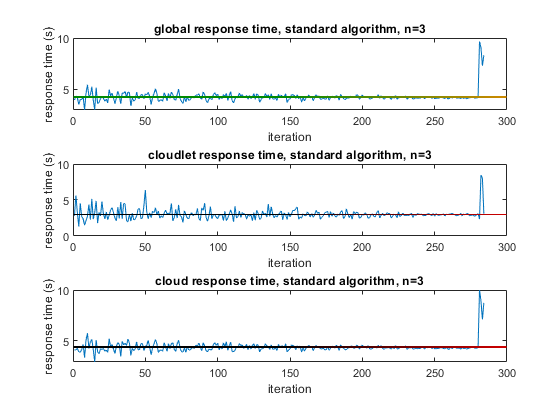

plotSteadyState(globalST, cloudletST, cloudST)

Per sapere la distribuzione dei tempi di risposta per le diverse combinazioni di classe - sistema possiamo chia mare la seguente funzione

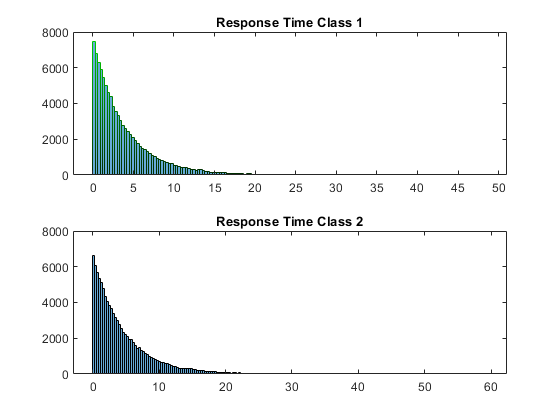

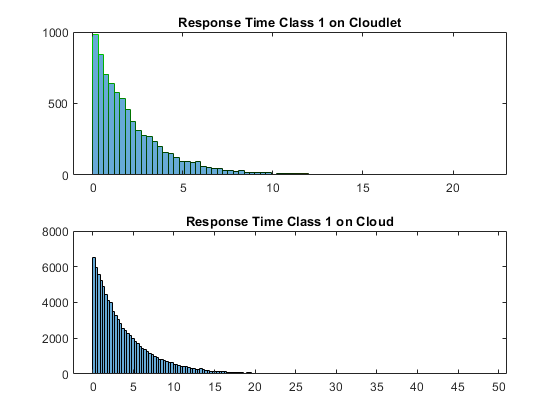

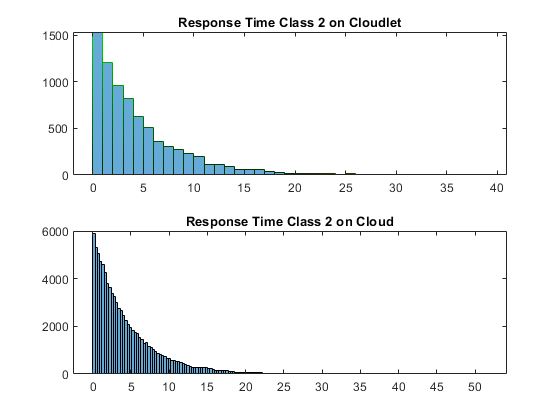

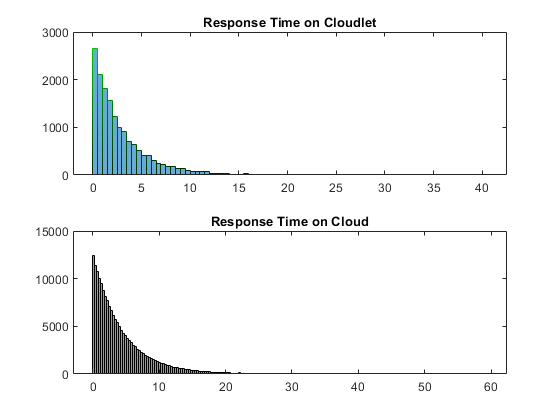

plotResponseTimeInOneSimulation;

Supponiamo di voler sapere dopo quanto tempo raggiungono la media. Per questo motivo sono state salvati i valori relativi alle medie calcolate iterativamente relative ai primi mille pacchetti inviati

(mentre il cloudlet converge subito, cloud e global convergono precisamente dopo 20 minuti circa)

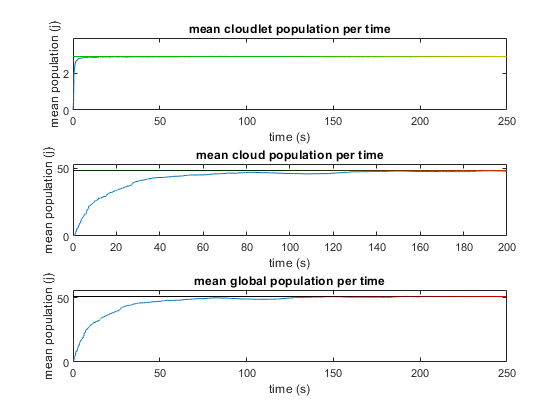

meansInOneSimulation(avgPopulationGlobal, avgPopulationCloudlet, avgPopulationCloud);

Per avere invece l'utilizzazione dei diversi server

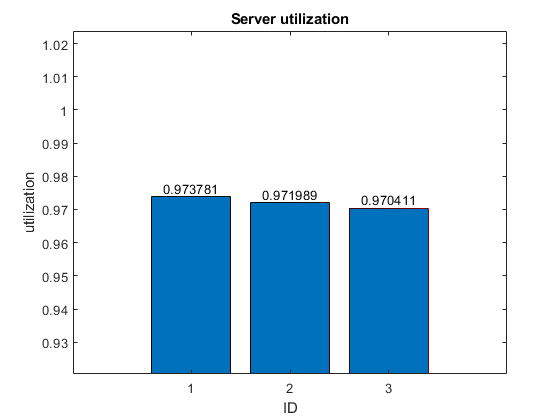

serverStatus;

Così come abbiamo fatto per i tempi di risposta, per stampare la media delle popolazioni attraverso le diverse iterazioni possiamo chiamare la seguente funzione

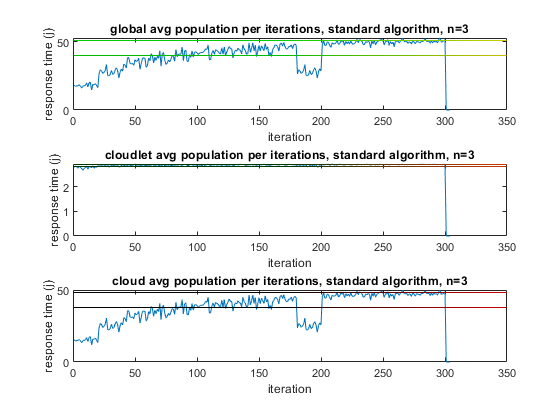

avgJobs(avgPopulationGlobal, avgPopulationCloudlet, avgPopulationCloud);

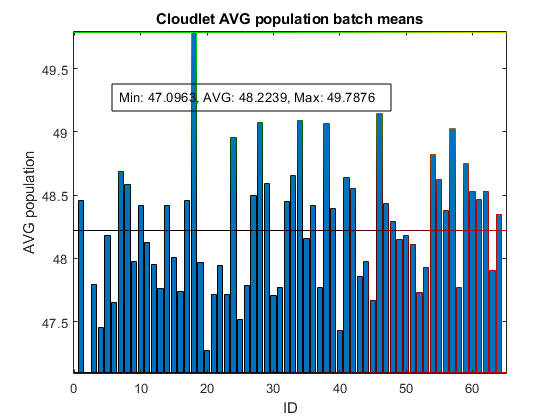

batchMeansPlot;

## Varianze Popolazioni

Sappiamo che la formula della varianza è 


$$Var(X) = E[X^2] - E[X]^2$$


A questo punto è molto semplice calcolare la varianza dei job all'interno del Cloudlet. Avendo risolto precedentemente la catena di Markov, possiamo calcolare per i valori globali

avg = 0*pstates(1) + 1*(pstates(2) + pstates(4)) + 2*(pstates(3) + pstates(5) + pstates(6)) + 3*(pstates(7) + pstates(8) + pstates(9) + pstates(10));
avg_squared = 0*pstates(1) + 1*(pstates(2) + pstates(4)) + 4*(pstates(3) + pstates(5) + pstates(6)) + 9*(pstates(7) + pstates(8) + pstates(9) + pstates(10));
Var_global_cloudlet = avg_squared - avg^2

Var_global_cloudlet = 0.0862

Per le singole classi invece

avg = 0*pstates(1) + 1*(pstates(4) + pstates(5) + pstates(10)) + 2*(pstates(6) + pstates(7)) + 3*(pstates(8));
avg_squared = 0*pstates(1) + 1*(pstates(4) + pstates(5) + pstates(10)) + 4*(pstates(6) + pstates(7)) + 9*(pstates(8));
Var_class1_cloudlet = avg_squared - avg^2

Var_class1_cloudlet = 0.6877

avg = 0*pstates(1) + 1*(pstates(2) + pstates(5) + pstates(7)) + 2*(pstates(3) + pstates(10)) + 3*(pstates(9));
avg_squared = 0*pstates(1) + 1*(pstates(2) + pstates(5) + pstates(7)) + 4*(pstates(3) + pstates(10)) + 9*(pstates(9));
Var_class2_cloudlet = avg_squared - avg^2

Var_class2_cloudlet = 0.7109

Per quanto riguarda l'infinite server è possibile ricondursi al calcolo della varianza tramite formule matematiche. Sappiamo infatti che notoriamente la probabilità di essere nello stato $i$ in un infinite server è dato da 


$$\pi_k = \frac{(\frac{\lambda}{\mu})^ke^{-\frac{\lambda}{\mu}}}{k!} $$


il numero medio di job è dato quindi da 


$$E[X]= \sum_{k=0}^{\infty}k\frac{(\frac{\lambda}{\mu})^ke^{-\frac{\lambda}{\mu}}}{k!} $$


utilizzando a questo punto la proprietà che $\sum_{i=0}^{\infty}i\frac{x^i}{i!} = xe^x$ è facile arrivare alla conclusione che 


$$E[X]= \sum_{k=0}^{\infty}k\frac{(\frac{\lambda}{\mu})^ke^{-\frac{\lambda}{\mu}}}{k!}  = e^{-\frac{\lambda}{\mu}}(\frac{\lambda}{\mu})e^{\frac{\lambda}{\mu}} = \frac{\lambda}{\mu}$$


per il calcolo della varianza bisogna ora calcolare $E[X^2] - E[X]^2$


$$E[X^2] = \sum_{k=0}^{\infty}k^2\frac{(\frac{\lambda}{\mu})^ke^{-\frac{\lambda}{\mu}}}{k!} $$


è possibile utilizzare la serie matematica notevole $\sum_{i=0}^{\infty}i^2\frac{x^i}{i!} = (x+x^2)e^x$. Quindi seguendo i successivi passaggi matematici si ottiene che


$$E[X^2] = \sum_{k=0}^{\infty}k^2\frac{(\frac{\lambda}{\mu})^ke^{-\frac{\lambda}{\mu}}}{k!}  = e^{-\frac{\lambda}{\mu}}((\frac{\lambda}{\mu}) + (\frac{\lambda}{\mu})^2)e^{\frac{\lambda}{\mu}} = \frac{\lambda}{\mu} + (\frac{\lambda}{\mu})^2$$



$$Var = \frac{\lambda}{\mu} + (\frac{\lambda}{\mu})^2 - (\frac{\lambda}{\mu})^2 = \frac{\lambda}{\mu} = E[X]$$
